# WindSimFaster: WindSimFast, but faster

This MATLAB tutorial focuses on simulating spatially correlated wind fields. It starts by preparing the MATLAB environment, including clearing variables and setting function paths. The tutorial covers the setup of time and frequency definitions crucial for capturing wind dynamics over time.The spatial grid setup is explained next, defining nodes along the y and z axes to create a mesh for wind simulation. This step allows for the simulation of wind speeds at various spatial points.The mean wind speed profile is introduced, calculating mean wind speed at each node based on the logarithmic wind profile equation. 

Uncorrelated wind velocity histories are then generated for each node using the Kaimal spectrum model. This simulates the natural variability and turbulence in wind fields. The tutorial highlights the introduction of spatial correlation into the wind field using Davenport's coherence model, simulating how wind speeds correlate across different points in space.

By the end of the tutorial, participants will have learned to simulate and analyze spatially correlated wind fields in MATLAB. The tutorial is designed for engineers, researchers, and students in wind engineering or atmospheric science.

## Time and frequency definitions

clearvars;close all;clc;
addpath ./functions
fs = 6; % sampling frequency (in Hertz)
M = 13; % M is the power of 2: If M = 10, 2^M = 1024 time step
[t,f] = getSamplingPara(M,fs);

Duration of target time series is 0.379 hours, i.e. 1.37e+03 sec 



N=numel(t); % number of time step (should be equal to 2^M)
Nfreq = numel(f); % number of frequency step (should be equal to 2^(M-1))
dt = median(diff(t)); % time step (should be equal to 1/fs)

## Grid definition

Nyy = 20; % number of nodes along the y axis
Nzz = 20; % number of nodes along the z axis
ymin = -120;
ymax = 120;
zmin= 10;
zmax = zmin +270;
y = linspace(ymin,ymax,Nyy);
z = linspace(zmin,zmax,Nzz);
[Y,Z] = meshgrid(y,z);
M = numel(Z(:));

## Mean wind speed profile

u_star = 0.8; % Friction velocity (m/s);
kappa = 0.4; % von karman constant
z0 = 0.01; % roughness length;
logProfile = @(u_star,z,z0,kappa)  u_star/kappa.*log(z./z0);
meanU = logProfile(u_star,Z,z0,kappa);

## Generate uncorrelated wind velocity histories

tic
Nf = numel(f);
u = zeros(N,M);
Su = zeros(Nf,M);
dummyU = meanU(:);
dummyZ = Z(:);

rng(1) % for reprodcuibility only!
for ii=1:M
    [Su(:,ii)] = KaimalModel(dummyU(ii),dummyZ(ii),f,u_star);
    [u(:,ii),t] = randomProcess(f,Su(:,ii));
end
toc

Elapsed time is 0.604348 seconds.


## Introduction a spatial correlation

Cy = 3; % Davenport coherence coefficient for lateral separations
Cz = 6; % Davenport coherence coefficient for vertical separations
[u_corr] = windSimFaster(Y,Z,meanU,Cy,Cz,f,u);

Elapsed time is 25.406976 seconds.


u_corr = reshape(u_corr,[N,Nzz,Nyy]);

## Time series visualization

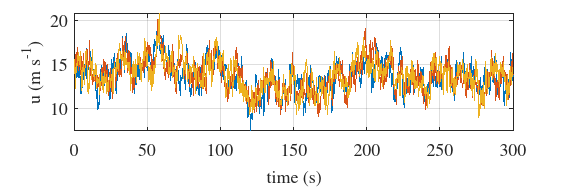

[~, indEnd] = min(abs(t-300));
clf;close all;
figure('position',[ 500         322        600         200])
plot(t(1:indEnd),squeeze(u_corr(1:indEnd,1,1:2:6)))
ylabel('u (m s^{-1})')
xlabel('time (s)')
set(gcf, 'color', 'w'); % Set figure background color
set(findall(gcf, '-property',...
    'FontSize'), 'FontSize', 14, 'FontName', 'Times'); % Set font properties
grid on; % Enable grid for readability
axis tight; % Tighten axis limits

## Mean wind speed profile

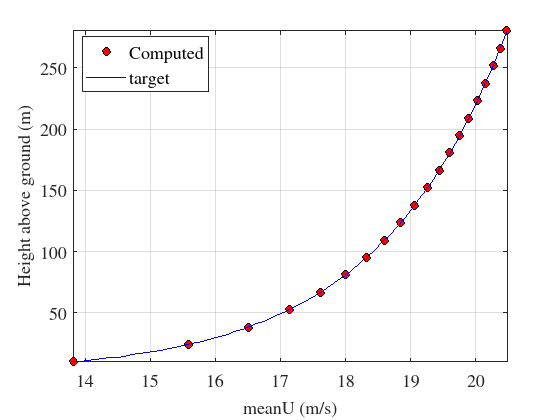

figure
plot(squeeze(mean(u_corr(:,:,1))),z,'ko','markerfacecolor','r')
hold on
z1 = logspace(log10(z(1)),log10(z(end)),60);
plot(logProfile(u_star,z1,z0,kappa),z1,'b')
legend('Computed','target','location','best')
xlabel('meanU (m/s)')
ylabel('Height above ground (m)')
set(gcf, 'color', 'w'); % Set figure background color
set(findall(gcf, '-property',...
    'FontSize'), 'FontSize', 14, 'FontName', 'Times'); % Set font properties
grid on; % Enable grid for readability
axis tight; % Tighten axis limits

## Pseudocolorplot

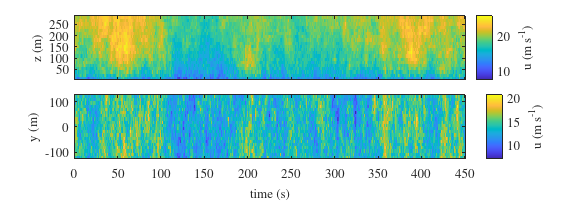

[~, indEnd] = min(abs(t-450));
figure('position',[ 173         322        1001         375])
tiledlayout(2,1,"TileSpacing","compact")
nexttile
imagesc(t(1:indEnd),z,squeeze(u_corr(1:indEnd,:,1))');axis xy
ylabel('z (m)')
% xlabel('time (s)')
c = colorbar;
ylabel(c,'u (m s^{-1})')
set(gca,'xticklabel',[])
nexttile
imagesc(t(1:indEnd),y,squeeze(u_corr(1:indEnd,1,:))');axis xy
ylabel('y (m)')
xlabel('time (s)')
c = colorbar;
ylabel(c,'u (m s^{-1})')

set(gcf,'color','w')
set(findall(gcf, '-property',...
    'FontSize'), 'FontSize', 10, 'FontName', 'Times'); % Set font properties
axis tight; % Tighten axis limits

## Power spectral density

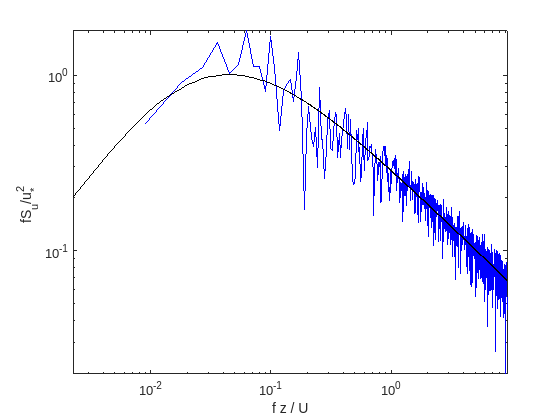

u = reshape(u,[N,Nzz,Nyy]);
[~,indZ]=min(abs(Z(:,1)-50));
Nf = round(N/4); % numbe of points for each segments (50% overlapping)
[Su0,f0]=pwelch(detrend(squeeze(u_corr(:,indZ,1))),Nf,round(Nf/2),Nf,fs);
Su0 = f0.*Su0./u_star.^2;
fr0 = Z(indZ,1)./meanU(indZ,1).*f0;
fr = Z(indZ,1)./meanU(indZ,1).*f;
coeff = f(:)./u_star.^2;
figure
loglog(fr0,Su0,'b')
hold on; box on;
loglog(fr,coeff.*Su(:,indZ),'k')
xlabel('f z / U')
ylabel('fS_u/u^2_* ')
axis tight

set(gcf,'color','w')

## Coherence along the y direction

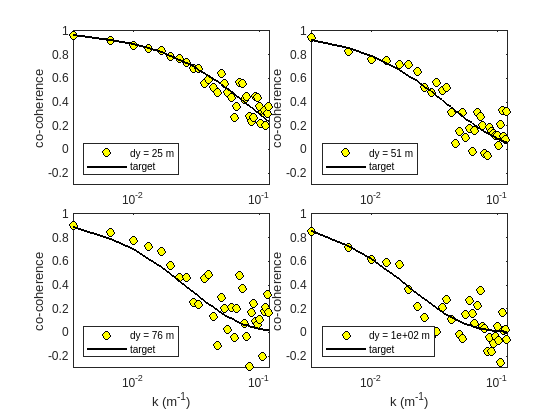


Nblock = 10; % a lot of block here to make it easier to visualize
Ncoh = round(N/Nblock);

distTarget = [25,50,75,100];
dy = abs(Y(1,:)'-Y(1,:)); % Matrix distance along y
dz = abs(Z(1,:)'-Z(1,:)); % Matrix distance along z
uCoh = 0.5*(meanU(1,:)'+meanU(1,:)); % Mean wind velocity between each nodes
% lateral separation
ay = Cy.*dy;
% vertical separation
az = Cz.*dz;
% Combine them into the coherence matrix for lateral and vertical
% separations
K = -sqrt(ay.^2+az.^2)./uCoh;
% Anonymous function
cohDavenport = @(K,f) exp(K.*f);

Ntarget = numel(distTarget);

figure
tiledlayout(2,2,"TileSpacing","tight")
for ii=1:Ntarget
    [~,indDist] = min(abs(dy(1,:)-distTarget(ii)));
    [cocoh,~,freq] = coherence(u_corr(:,1,1),u_corr(:,1,indDist),Ncoh,round(Ncoh/2),Ncoh,fs);
    k = 2*pi*freq./uCoh(1,indDist);
    nexttile
    semilogx(k,cocoh,'ko','markerfacecolor','y');
    box on;hold on
    plot(k,cohDavenport(K(1,indDist),freq),'k','linewidth',1.5);
    legend(['dy = ',num2str(dy(1,indDist),2),' m'],'target','location','southwest');
    xlim([0,0.12])
    ylim([-0.3,1])
    ylabel('co-coherence')
    if ii>2,        xlabel('k (m^{-1})');    end
    set(gcf,'color','w')
end

## Coherence along the z direction

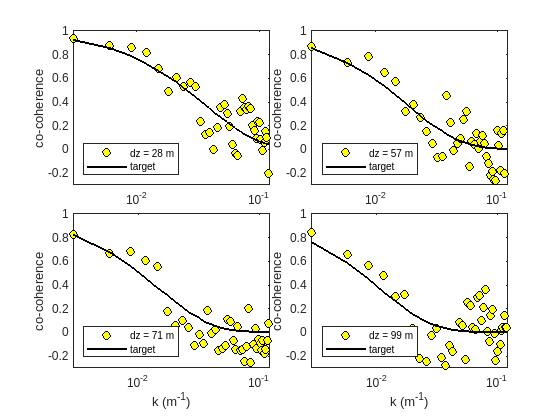


Nblock = 10; % a lot of block here to make it easier to visualize
Ncoh = round(N/Nblock);

distTarget = [25,50,75,100];
dy = abs(Y(:,1)'-Y(:,1)); % Matrix distance along y
dz = abs(Z(:,1)'-Z(:,1)); % Matrix distance along z
uCoh = 0.5*(meanU(:,1)'+meanU(:,1)); % Mean wind velocity between each nodes
% lateral separation
ay = Cy.*dy;
% vertical separation
az = Cz.*dz;
% Combine them into the coherence matrix for lateral and vertical
% separations
K = -sqrt(ay.^2+az.^2)./uCoh;
% Anonymous function
cohDavenport = @(K,f) exp(K.*f);

Ntarget = numel(distTarget);

figure
tiledlayout(2,2,"TileSpacing","tight")
for ii=1:Ntarget
    [~,indDist] = min(abs(dz(1,:)-distTarget(ii)));
    [cocoh,~,freq] = coherence(u_corr(:,1,1),u_corr(:,indDist,1),Ncoh,round(Ncoh/2),Ncoh,fs);
    k = 2*pi*freq./uCoh(indDist,1);
    nexttile
    semilogx(k,cocoh,'ko','markerfacecolor','y');
    box on;hold on
    plot(k,cohDavenport(K(indDist,1),freq),'k','linewidth',1.5);
    legend(['dz = ',num2str(dz(indDist,1),2),' m'],'target','location','southwest');
    xlim([0,0.12])
    ylim([-0.3,1])
    ylabel('co-coherence')
    if ii>2,        xlabel('k (m^{-1})');    end
    set(gcf,'color','w')
end